# Plot predicted properties evolution in the composition space

## Import the datasets that contain the predictions

addpath('./modules')

path=getenv('DATASETS_DIR');
databaseNN=path+"Predictions_NN_mechanical_model.csv";
databaseRF=path+"Predictions_RF_mechanical_model.csv";

Preparation of the tables (to adapt depending on your dataset)

predNN=readtable(databaseNN);

predNN=predNN(:,2:end); % suppress first column and keep only compositions and outputs
predNN.Zr=predNN.Zr/100; % composition in % and not in percent rate
predNN.Nb=predNN.Nb/100;
predNN.Mo=predNN.Mo/100;
predNN.Ti=predNN.Ti/100;
predNN.Cr=predNN.Cr/100;

predRF=readtable(databaseRF);

predRF=predRF(:,2:end); % suppress first column and keep only compositions and outputs
predRF.Zr=predRF.Zr/100;
predRF.Nb=predRF.Nb/100;
predRF.Mo=predRF.Mo/100;
predRF.Ti=predRF.Ti/100;
predRF.Cr=predRF.Cr/100;

## Import connexion tables: contains indices of neighbouring compositions

connexions_table=readtable('./matrice_connection.csv'); % import connexion matrix

## Define the columns that contains the predicted properties

Phase class is predicted with NN and mechanical properties from RF.

column_EBSD=predNN.NN_PhasePredictionFromEBSDClass;
column_XRD=predNN.NN_PhasePredictionFromXRDClass;
column_H=predRF.RF_HardnessPrediction_GPa_;
column_deltaH=predRF.deltaH ;

## Prepare composition space plotting

nb_elements=5;
name_elements=["Zr","Nb","Mo","Ti","Cr"];

x = gallery('uniformdata',[nb_elements 1],0);
y = gallery('uniformdata',[nb_elements 1],1);
z = gallery('uniformdata',[nb_elements 1],2);
DT = delaunayTriangulation(x,y,z);
[T,Xb] = freeBoundary(DT);
TR = triangulation(T,Xb);
F = faceNormal(TR);

## Define amorphous, transition, crystalline domains

Amorphous domain contains the amorphous compositions for which all neighbouring composition are also amorphous.

Crystallyne domain contains the crystalline compositions for which all neighbouring composition are also crystalline.

Transition domain contains compositions for which neighbouring compositions can be of different phases.

phase_cryst=[];
phase_amorph=[];
phase_trans=[];

% Indices of the points are classified in the different domains
for i = 1:size(connexions_table,1)
    index_point=table2array(connexions_table(i,1));
    phase=[table2array(predNN(index_point,6)),table2array(predNN(index_point,7))];
    index_neigh=connexions_table(i,2:end);
    phases_neigh=[table2array(predNN(table2array(index_neigh),6)),table2array(predNN(table2array(index_neigh),7))];
    
    if sum(phase)>=1
        if sum(sum(phases_neigh))>=5
            phase_cryst=[phase_cryst,index_point];
        else
            phase_trans=[phase_trans,index_point];
            
        end
    end
    
    if sum(sum(phase))==0
        if sum(phases_neigh)==0
            phase_amorph=[phase_amorph,index_point];
        else 
           phase_trans=[phase_trans,index_point];
        end
    end
end


From classed indices, we filter in RF table the compositions corresponding to the different domains. 

The NN predictions table allows to **filter **the RF predictions tables to keep the predicted mechnical properties corresponding to different phase domains

compo_amorph=predRF(phase_amorph,:);
compo_trans=predRF(phase_trans,:);
compo_cryst=predRF(phase_cryst,:);

## Plot phase domains as alphashape

Coordinates of the compositions on the different domains

coord_amorph=table2array(compo_amorph(:,1:5))*[x y z];
coord_trans=table2array(compo_trans(:,1:5))*[x y z];
coord_cryst=table2array(compo_cryst(:,1:5))*[x y z];


Use the plot_prediction function

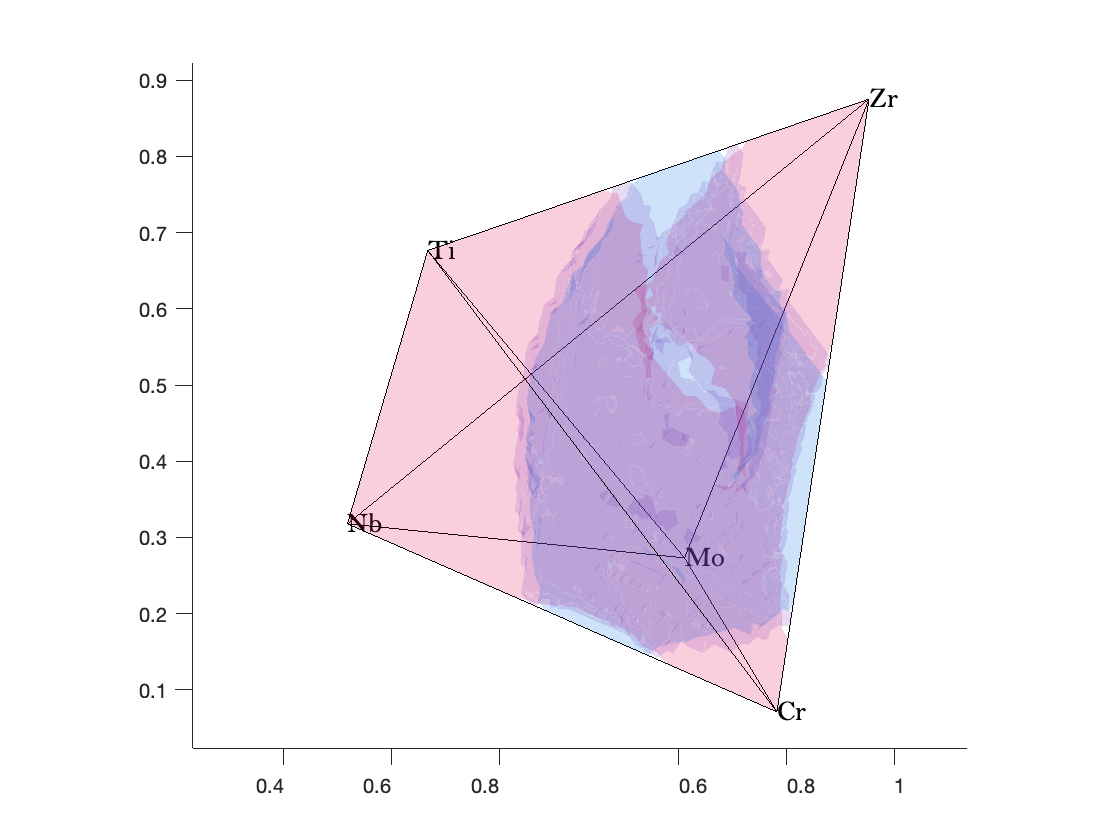

cell_coordinates={coord_amorph,coord_trans,coord_cryst};
cell_type_plot={"alphashape","alphashape","alphashape"};
cell_size={20,20,20};
cell_colors={[0,104,222]./255,[130,68,192]./255, [222,8,85]./255};

plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size)

## Plot specific values of hardness and ductility

### Define isovalues to plot

max_value_H_cryst_domain= 21;
max_value_deltaH_cryst_domain=0.84;

max_value_H_amorphous_domain= 18;
max_value_deltaH_amorphous_domain=0.74;

### Define masks 

Mask for compositions

mask_H1_amorph= (abs(column_H-max_value_H_amorphous_domain)<1 & column_EBSD==0 & column_XRD==0);

mask_deltaH1_amorph=(abs(column_deltaH-max_value_deltaH_amorphous_domain)<0.05  & column_EBSD==0 & column_XRD==0 );

mask_H1_cryst= (abs(column_H-max_value_H_cryst_domain)<1 & (column_EBSD==1 | column_XRD==1));

mask_deltaH1_cryst=abs(column_deltaH-max_value_deltaH_cryst_domain)<0.1 &(column_EBSD==1 | column_XRD==1);

### Interpolation of isovalues

[selection_coord_H1_amorph,compo_iso_list_H1_amorph,coord_iso_list_H1_amorph] = select_interp_compo(predRF,[1:5], column_H, max_value_H_amorphous_domain, mask_H1_amorph, connexions_table, "True", x,y,z);

[selection_coord_H1_cryst,compo_iso_list_H1_cryst,coord_iso_list_H1_cryst] = select_interp_compo(predRF,[1:5], column_H, max_value_H_cryst_domain, mask_H1_cryst, connexions_table, "True", x,y,z);

[selection_coord_deltaH1_amorph,compo_iso_list_deltaH1_amorph,coord_iso_list_deltaH1_amorph] = select_interp_compo(predRF,[1:5], column_deltaH, max_value_deltaH_amorphous_domain, mask_deltaH1_amorph, connexions_table, "True", x,y,z);

[selection_coord_deltaH1_cryst,compo_iso_list_deltaH1_cryst,coord_iso_list_deltaH1_cryst] = select_interp_compo(predRF,[1:5], column_deltaH, max_value_deltaH_cryst_domain, mask_deltaH1_cryst, connexions_table, "True", x,y,z);


### Plot isovalues.

cell_coordinates={coord_amorph, coord_iso_list_H1_amorph}

cell_coordinates = 1×2 cell array
    {108133×3 double}    {47×3 double}


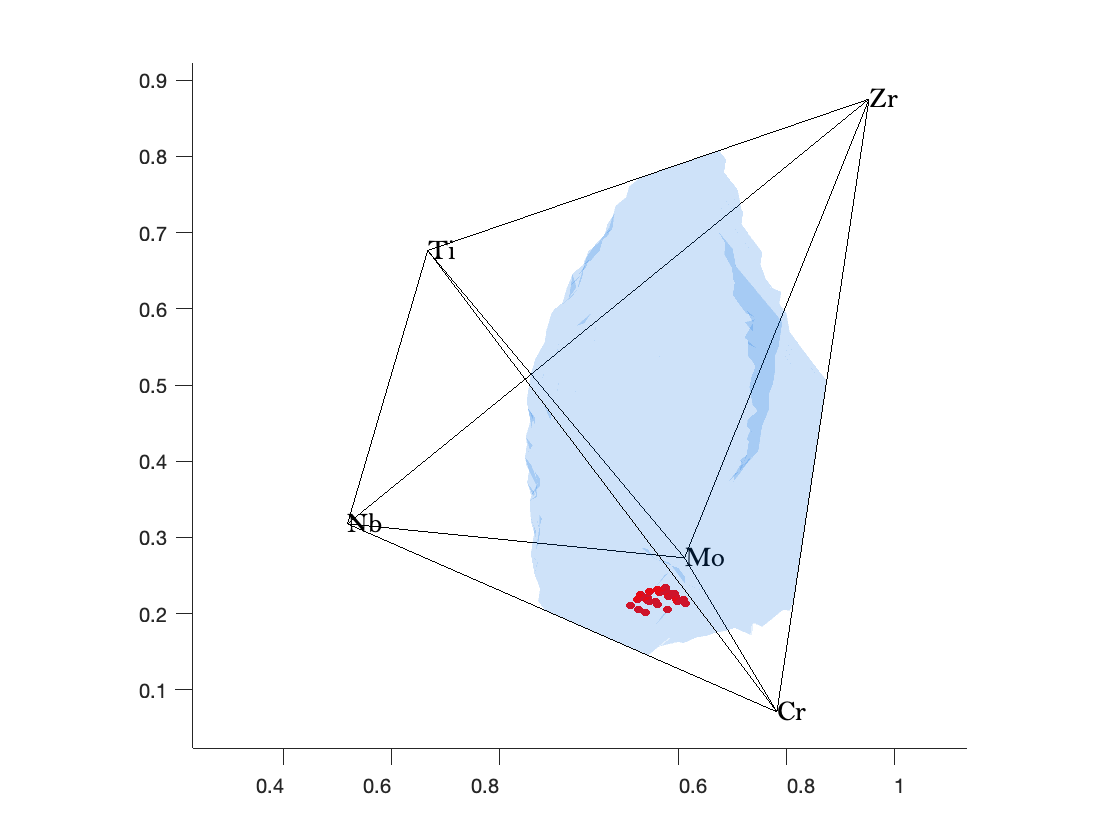

cell_type_plot={"alphashape","scatter"};
cell_size={0, 21};
color=autumn;% If you plot more than 1 value of H, use a color map to define the colors
cell_colors={[0,104,222]./255,color(1,:)};
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size)


cell_coordinates={coord_amorph, coord_iso_list_deltaH1_amorph}

cell_coordinates = 1×2 cell array
    {108133×3 double}    {40×3 double}


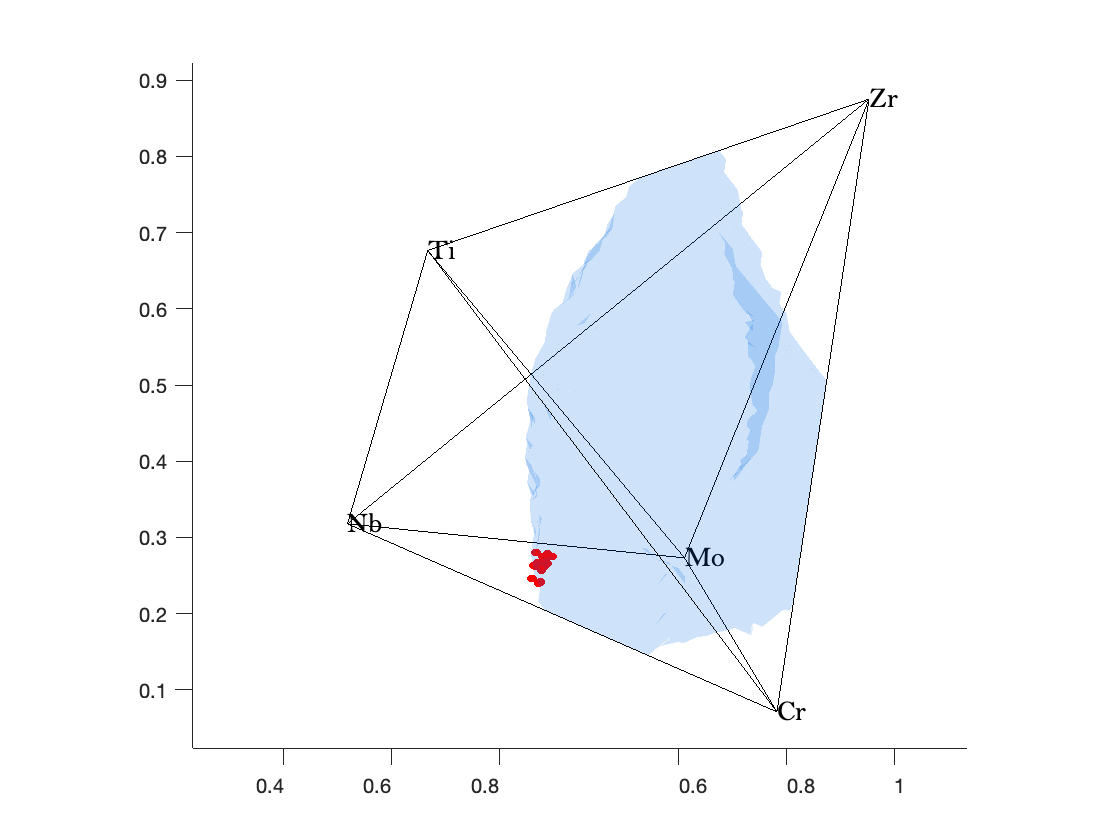

cell_type_plot={"alphashape","scatter"};
cell_size={0,21};
color=autumn;
cell_colors={[0,104,222]./255,color(1,:)};
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size)


cell_coordinates={coord_cryst, coord_iso_list_H1_cryst}

cell_coordinates = 1×2 cell array
    {181955×3 double}    {14×3 double}


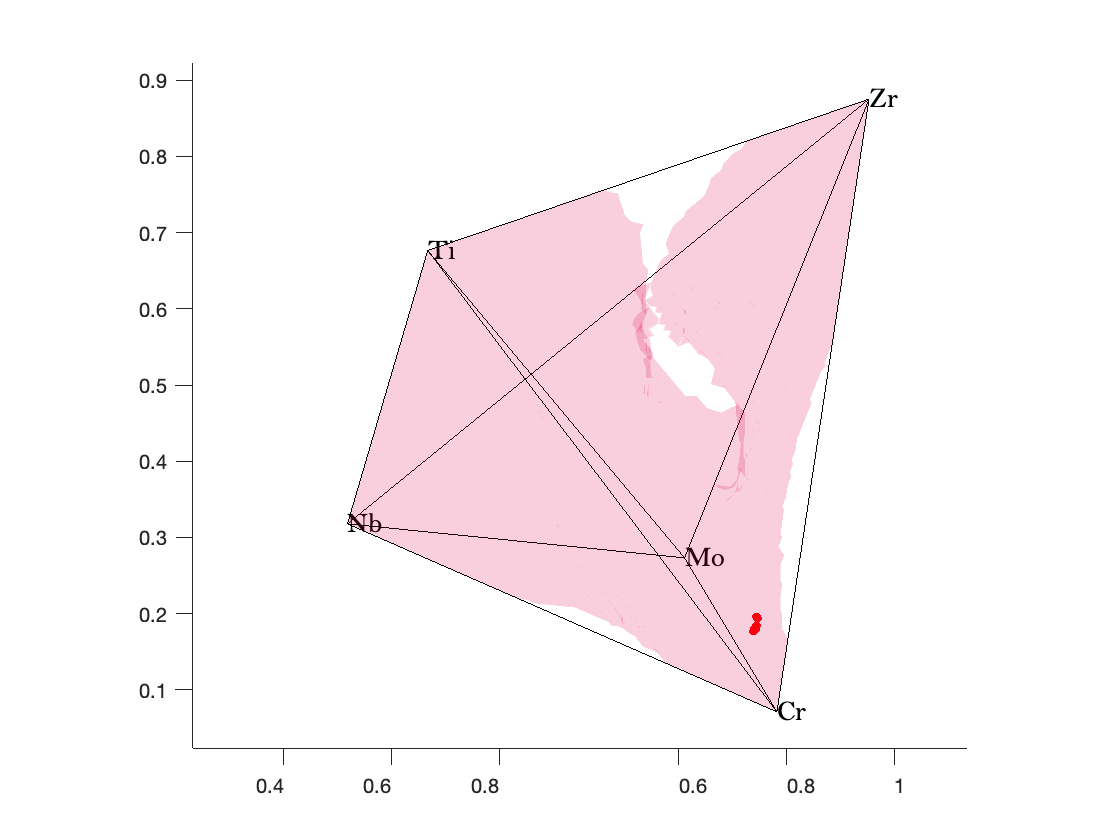

cell_type_plot={"alphashape","scatter"};
cell_size={0, 21};
color=autumn;
cell_colors={[222,8,85]./255,color(1,:)};
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size)



cell_coordinates={coord_cryst, coord_iso_list_deltaH1_cryst}

cell_coordinates = 1×2 cell array
    {181955×3 double}    {250×3 double}


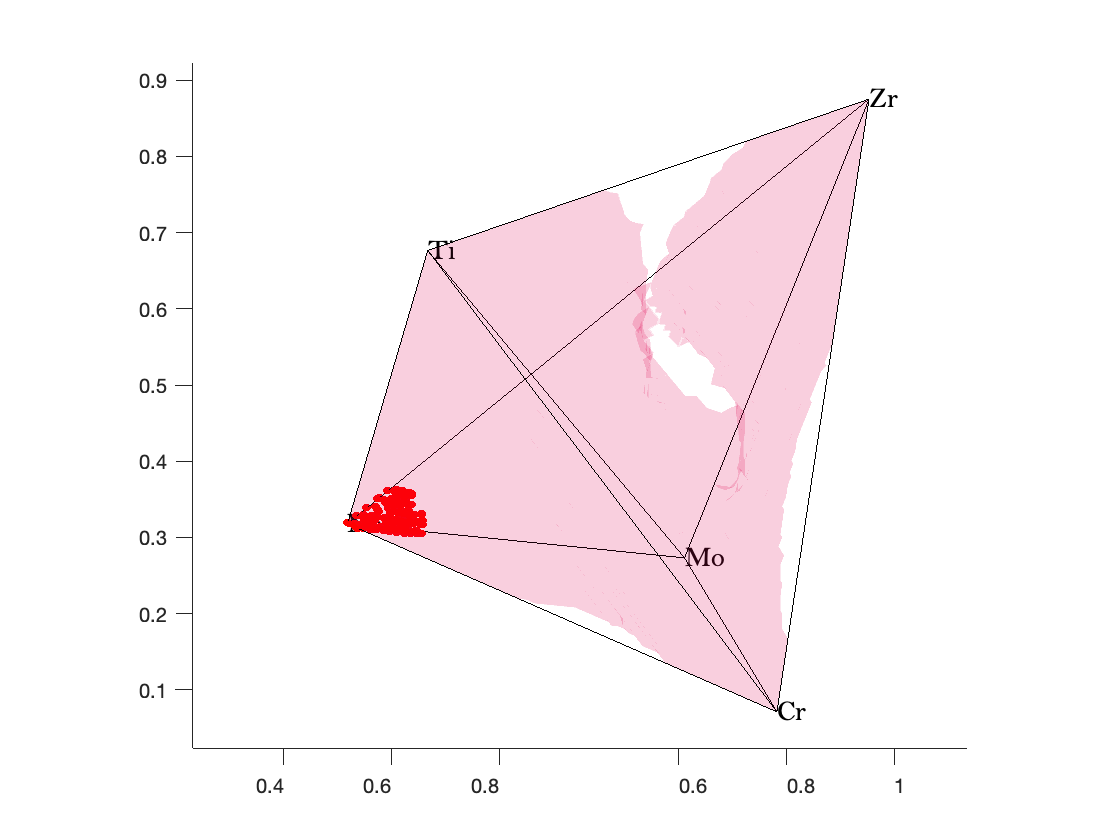

cell_type_plot={"alphashape","scatter"};
cell_size={0, 21};
color=autumn;
cell_colors={[222,8,85]./255,color(1,:)};
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size)